## Back to basics: Step 1.

## State model


$$x_{t+1} =x_t +v_{xt} \cdot h+w_t$$



$$y=||r-r^{\left(i\right)} ||_2 \;+v_t$$



$$\mathit{\mathbf{x}}=\left\lbrack \begin{array}{c}
x\\
v_x 
\end{array}\right\rbrack$$
    
$$A=\left\lbrack \begin{array}{cc}
1 & h\\
0 & 1
\end{array}\right\rbrack$$



$$x_{t+1} ={Ax}_t +{Gw}_t$$



$$y_t =h\left(x_t ,v_t \right)$$


The model dynamics are linear, the output is not.

1 - dimensional travel random walk. Position and velocity as the states of the system.

This is very similar to the example in `5_ekf.ipynb`

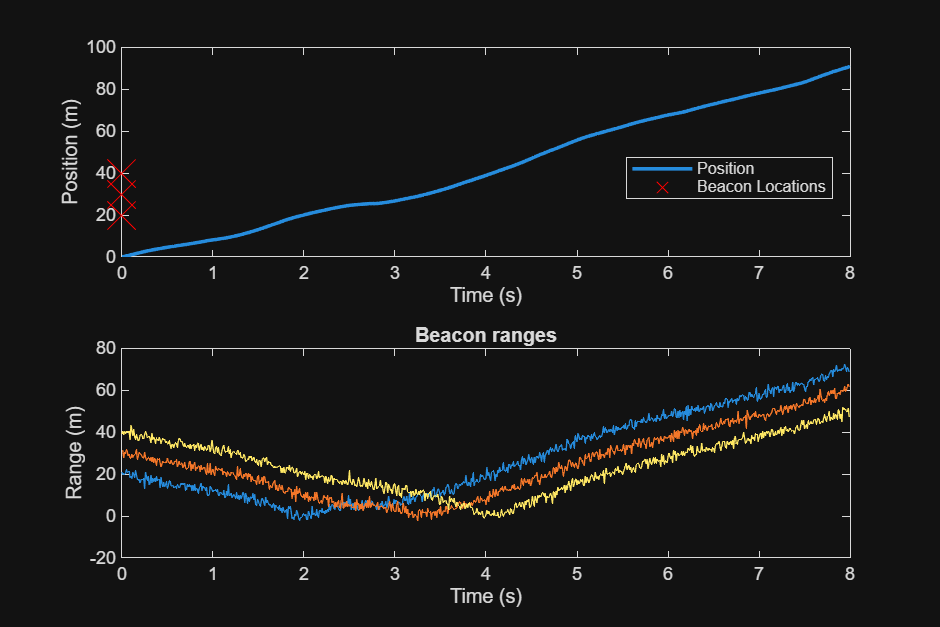

% Make sure to add Casadi to path and import it.
import casadi.*

% Setup.
fs = 100;
ht = 1/fs;

% State transition matrix.
A = [1 ht;
     0 1];

% Noise multiplier, only want noise on the velocity term.
G = [0; 1];

% Define where the beacons are on the track.
beaconLocations = [20 30 40]';
nBeacons = length(beaconLocations);

% Jacobian set up.
% Variable.
x = MX.sym('x', 2);

% Define the function. Simple in one dimension. L2 Norm is Euclidean
% distance.
h = sqrt((x(1) - beaconLocations).^2);

% Jacobian here.
jh = jacobian(h, x);
Jhx = Function('h', {x}, {h});
Jh = Function('Jh', {x}, {jh});

% Measurement noise.
mu = zeros(1, nBeacons);
r = 1.5;
R = r^2 * eye(nBeacons);

nSamples = 800;
timeVector = (0 : nSamples) * ht;

stateVector = zeros(2, nSamples + 1);
measurementVector = zeros(nBeacons, nSamples);

stateVector(:, 1) = [0 10]';

for t = 1 : nSamples

    processNoise = randn * 0.5;

    % Note that there's no input terms here. They're in the script for
    % testing, but omitted because the model doesn't call for it.
    stateVector(:, t + 1) = A * stateVector(:, t) + G * processNoise;

    currentPosition = stateVector(1, t);
    distFromBeacons = abs(currentPosition - beaconLocations);

    % NOTE HERE: This line is a method for scaling the noise based on the
    % distance from the beacon. This is a cool way to model the
    % uncertainty, but R has to be passed back into the Kalman filter. The
    % loop is split here just to make everything nice and readable, but if
    % we get time to do it, we can come back to this.

    % measurementNoise = (r * sqrt(distFromBeacons)) .* randn(nBeacons, 1);

    % Actual noise model provided.
    measurementNoise = mvnrnd(mu, R)';

    measurementVector(:, t) =  distFromBeacons + measurementNoise;

end

f = figure;
f.Position = [0 0 1200 800];
tiledlayout(2, 1)
nexttile
plot(timeVector, stateVector(1, :), 'LineWidth', 1.8, 'DisplayName', 'Position')
hold on
plot(mu, beaconLocations, 'rx', 'MarkerSize', 20, 'DisplayName', 'Beacon Locations')
xlabel('Time (s)')
ylabel('Position (m)')
legend('Location', 'best')

nexttile
grid on;
plot(timeVector(1 : end - 1), measurementVector)
xlabel('Time (s)'); ylabel('Range (m)'); title('Beacon ranges')

This makes sense, the object travels towards each beacon location, (displacement is approximately 0 at this point relative to the beacon), then travels away.

Note: Because the velocity is not driven and is unconstrained in this example, it may take a few runs before you get the desired behaviour. 

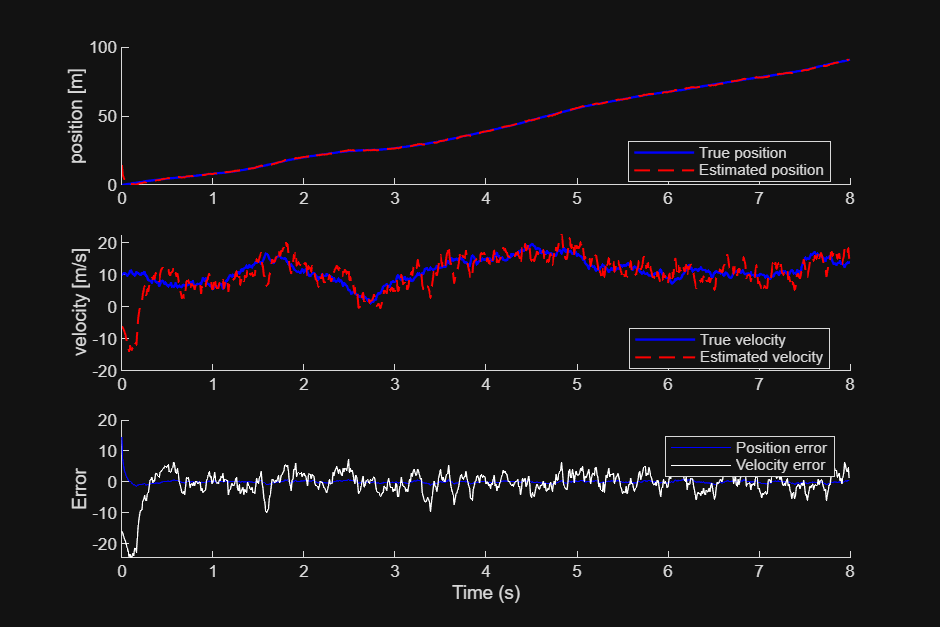

x_mu = zeros(2, nSamples);
sigma_mu = cell(1, nSamples);

% Initial estimate (deliberately off so we see convergence)
x_tu = [25; -6];
sigma_tu = diag([10, 5]);

for k = 1 : nSamples
    % Jacobian steps to compute before Kalman Filter.
    p_pred = x_tu(1);
    h_x = full(Jhx(p_pred));
    C_lin = full(Jh(p_pred));
 
    % Keep a log of sigma and the estimated state.
    [sigma_mu{:, k}, x_mu(:, k)] = measurementUpdate(sigma_tu, x_tu, ...
        measurementVector(:, k), C_lin, R, h_x);

    % Note the empty input terms. This is from the testing script which had
    % inputs driving the system, set to 0 here.
    [sigma_tu, x_tu] = timeUpdate(sigma_mu{:, k}, x_mu(:, k), A, [0; 0], ...
        0, Q, G);

end

f = figure;
f.Position = [0 0 1200 800];
tiledlayout(3, 1)

% Plots.
nexttile
hold on;
plot(timeVector, stateVector(1,:), 'b', 'LineWidth', 1.2, 'DisplayName', 'True position')
plot(timeVector(1 : end - 1), x_mu(1,:), 'r--', 'LineWidth', 1, 'DisplayName', 'Estimated position')
ylabel('position [m]');
legend('Location','best')

nexttile
hold on;
plot(timeVector, stateVector(2,:), 'b', 'LineWidth', 1.2, 'DisplayName', 'True velocity')
plot(timeVector(1 : end - 1), x_mu(2,:), 'r--', 'LineWidth', 1, 'DisplayName', 'Estimated velocity')
ylabel('velocity [m/s]')
legend('Location','best')

nexttile
hold on
positionError = x_mu(1,:) - stateVector(1,1 : end - 1);
velocityError = x_mu(2,:) - stateVector(2,1 : end - 1);
plot(timeVector(1 : end - 1), positionError, 'b', 'DisplayName', 'Position error')
plot(timeVector(1 : end - 1), velocityError, 'w', 'DisplayName', 'Velocity error')
ylabel('Error')
xlabel('Time (s)')
legend

Position estimation is so good here because we have 3 beacons. If we take out one of the beacons, it becomes worse. If we only have 1 beacon, the estimator doesn't know which side the beacon is on.

Bare in mind this is only in one dimension, if we bump it up to 2 dimensions, the effect will be exacerbated due to circumferential geometry.

function [sigma, x] = measurementUpdate(sigma, x, y, C, R, h_x)
    z = C * sigma * C' + R;
    x = x + sigma * C' * linsolve(z, y - h_x);
    sigma = sigma - sigma * C' * linsolve(z, C * sigma);
end

function [sigma, x] = timeUpdate(sigma, x, A, B, u, Q, G)
    x = A * x + B * u;
    sigma = A * sigma * A' + Q * (G * G');
end